# Denoising Diffusion Probabilistic Models

clc; clear all; close;

## Given an image $X\in {\mathbb{R}}^d$, the DDPM uses the variance schedule

## 
$$0<\beta_1 <\beta_2 <\cdots <\beta_N <1$$


## The forward process is given as

## $X_k =\sqrt{1-\beta_k }X_{k-1} +\sqrt{\beta_k }\varepsilon_k$ for $k=1,2,\cdots ,N$ and $\varepsilon_k ~N\left(0,I\right)$

## It is straightforward to show that

## 
$$X_k =\sqrt{{\bar{\alpha} }_k }X_0 +\sqrt{1-{\bar{\alpha} }_k }\varepsilon_k$$


## Therefore, if $X_0 ~N\left(\mu_0 ,\sigma_0^2 \right)$, we can infer that $X_k ~N\left({\sqrt{{\bar{\alpha} }_k }\mu }_0 ,{\bar{\alpha} }_k \sigma_0^2 +1-{\bar{\alpha} }_k \right)$for all $k$. Note that we will use the notation

## $\alpha_k =1-\beta_k$ and ${\bar{\alpha} }_k =\Pi_{i=1}^k \alpha_i$. 

## We formally assume $\Delta t=\frac{T}{N}$. In this case, we will take $\beta \left(t\right)=t$ so that $\beta_k =\beta \left(t_k \right)\Delta t={k\left(\Delta t\right)}^2$. We can easily check that $\left\lbrace \beta_k \right\rbrace$is monotonely-increasing and bounded by 1 if $\beta_N =\frac{T^2 }{N}<1$if $T<\sqrt{N}\ldotp$

%% numerical setup
T  = 10;   % terminal time
M  = 1000; % number of iterations
dt = T/M;  % time step size
N  = 2000; % number of particles
% ... parameters in DDPM ...
beta      = (1:M)*dt^2;
alpha     = 1 - beta;
alpha_bar = zeros(1,M); alpha_bar(1) = alpha(1);
for i = 2:M
alpha_bar(i) = alpha(i)*alpha_bar(i-1);
end
sigma_bar = [beta(1) sqrt( (1-alpha(2:end)).*(1-alpha_bar(1:end-1))./(1-alpha_bar(2:end)) )];
% ... exact mean and std ...
mu_0    = 3;
sigma_0 = 1.5;
% ... check approximations ...
% std = sqrt( exp( -0.5*( (1:M)*dt ).^2 )*sigma_0^2 + 1 - exp( -0.5*( (1:M)*dt ).^2 ) );

## Here, the "noise function" is given by $\varepsilon \left(x,t\right)=-\tilde{\sigma} \left(t\right)s\left(x,t\right)$, where $\tilde{\sigma} {\left(t\right)}^2 =$$1-\exp \left(-\int_0^t \beta \left(s\right)\textrm{ds}\right)$ and $s\left(x,t\right)=-\frac{x-\mu_t }{\sigma_t^2 }$ with $\mu_t =\exp \left(-\frac{1}{2}\int_0^t \beta \left(s\right)\textrm{ds}\right)\mu_0$ and $\sigma_t^2 =\exp \left(-\int_0^t \beta \left(s\right)\textrm{ds}\right)\sigma_0^2 +1-\exp \left(-\int_0^t \beta \left(s\right)\textrm{ds}\right)$.

% ... score and noise function ...
mu    = @(t) exp(-t^2/4)*mu_0;
std   = @(t) sqrt( exp(-t^2/2)*sigma_0^2 + 1 - exp(-t^2/2) );
s     = @(x,t) -( x - mu(t) )./std(t).^2;
sigma_tilde = @(t) sqrt( 1 - exp(-t^2/2) );
eps   = @(x,t) -sigma_tilde(t)*s(x,t);

## Now, we are ready to run the reverse process

## 
$$\left\lbrace \begin{array}{ll}
{\bar{X} }_{k-1} =\frac{1}{\sqrt{\alpha_k }}\left({\bar{X} }_k -\frac{1-\alpha_k }{\sqrt{1-{\bar{\alpha} }_k }}\varepsilon \left({\bar{X} }_k ,t_k \right)\right)+{\bar{\sigma} }_k Z & \textrm{for}\;k=N,N-1,\cdots ,1\\
X_N ~N\left({\sqrt{{\bar{\alpha} }_N }\mu }_0 ,{\bar{\alpha} }_N \sigma_0^2 +1-{\bar{\alpha} }_k \right) & 
\end{array}\right.$$


% ... initial condition ...
mu_M  = sqrt(alpha_bar(end))*mu_0;
std_M = sqrt( alpha_bar(end)*sigma_0^2 + 1 - alpha_bar(end) ); 
Xh_0 = zeros(N, M+1); Xh_0(:,M+1) = normrnd(mu_M,std_M,N,1);
% ... main loop ...
for i = M:-1:1
   ti = i*dt;
%    Xh_0(:,i) = 1/sqrt(alpha(i))*( Xh_0(:,i+1) + (1-alpha(i))*s(Xh_0(:,i+1),ti) ) ...
%              + sigma_bar(i)*randn(N,1);

   Xh_0(:,i) = 1/sqrt(alpha(i))*( Xh_0(:,i+1) - (1-alpha(i))/sqrt(1-alpha_bar(i))*eps(Xh_0(:,i+1),ti) ) ...
             + sigma_bar(i)*randn(N,1);
   
%    Xh_0(:,i) = 1/sqrt(alpha(i))*Xh_0(:,i+1) - (1-alpha(i))/sqrt(1-alpha_bar(i))*eps(Xh_0(:,i+1),ti) + ...
%                + sigma_bar(i)*randn(N,1);
end

## Let's output the numerical results

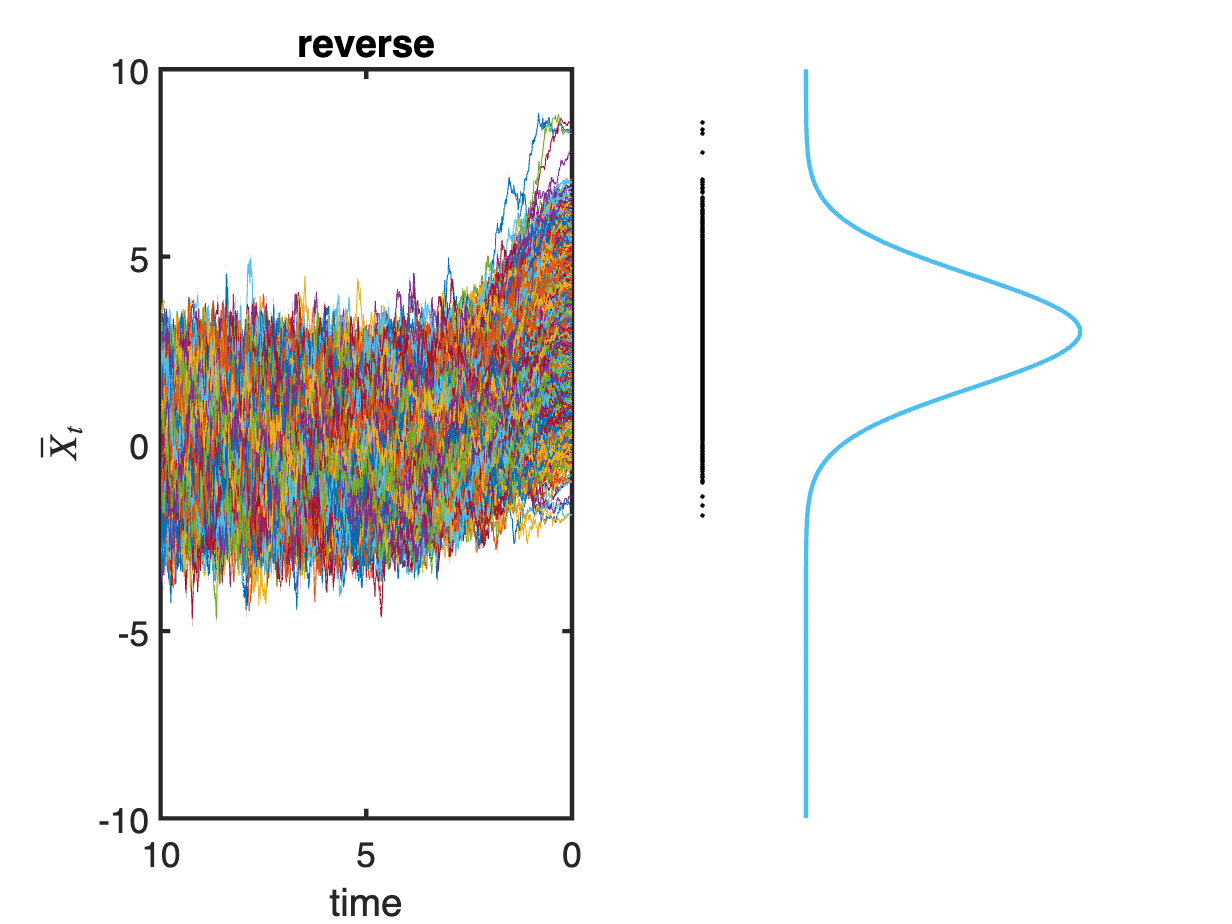

%% Compute mean and std from discrete data
mu_sde  = sum(Xh_0(:,1))/N;
std_sde = sqrt( sum((Xh_0(:,1)-mu_sde).^2)/N );
%% Output
subplot(1,2,1);
plot(0:dt:T,Xh_0); ylim([-10,10]); xlabel('time'); ylabel('$\bar{X}_t$','Interpreter','latex');
set(gca,'FontSize',16,'LineWidth',2, 'XDir','reverse'); title('reverse');
subplot(1,2,2);
plot(-0.1,Xh_0(:,1),'k.',normpdf(-10:0.1:10,mu_0,std(0)),-10:0.1:10,'LineWidth',2);
axis off; 

disp(['exact.mean = ', num2str(mu_0,'%.6f')]);

exact.mean = 3.000000


disp(['numer.mean = ', num2str(mu_sde,'%.6f')]);

numer.mean = 2.989836


disp(['exact.std  = ', num2str(std(0),'%.6f')]);

exact.std  = 1.500000


disp(['numer.std  = ', num2str(std_sde,'%.6f')]);

numer.std  = 1.484379
